# Tipos de ventana

### Ventana Cuadrada Original

En esta seccion creamos una venta primero creamos zeros y luego ponemos unos en un rango 

close all;
Tobs = 200

Tobs = 200

frec=-1:1/Tobs:1;
lenf=length(frec);
x=zeros(1,lenf);
x(101:301)=1;
t_square = real(ftot(x));

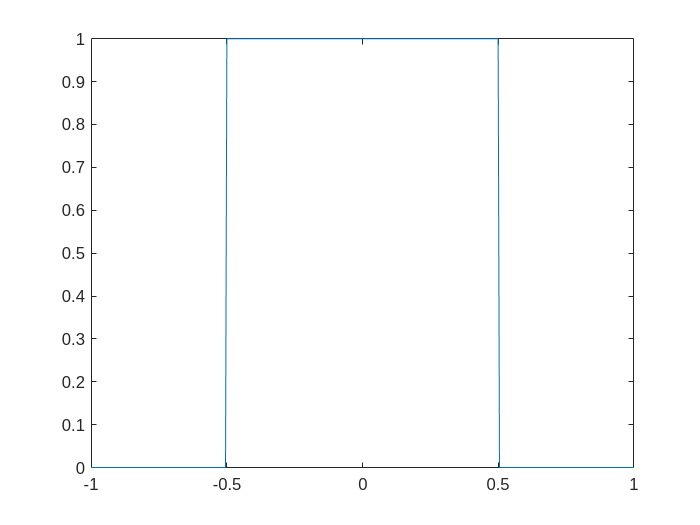

x = int32(x);
y=real(ftot(x));
plot(frec,x);

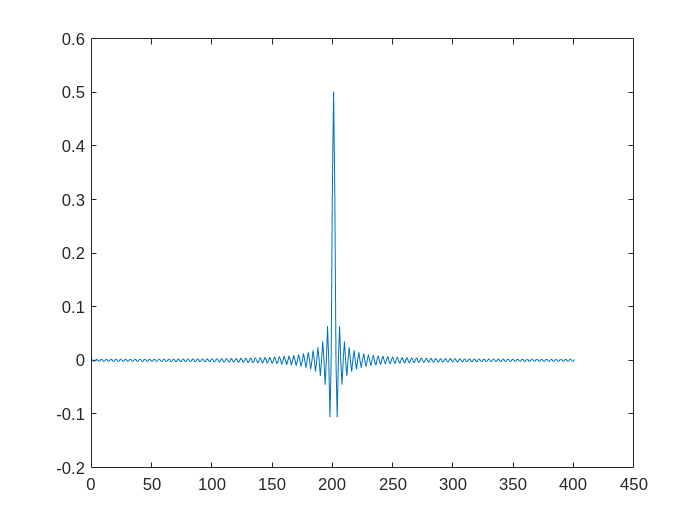

plot(t_square);

### Ventana Uniforme

Del centro "0" generamos 21 coeficientes. Al ser N muestras colocamos los coeficiente por $\frac{N}{2}\pm \frac{\textrm{coeff}}{2}$

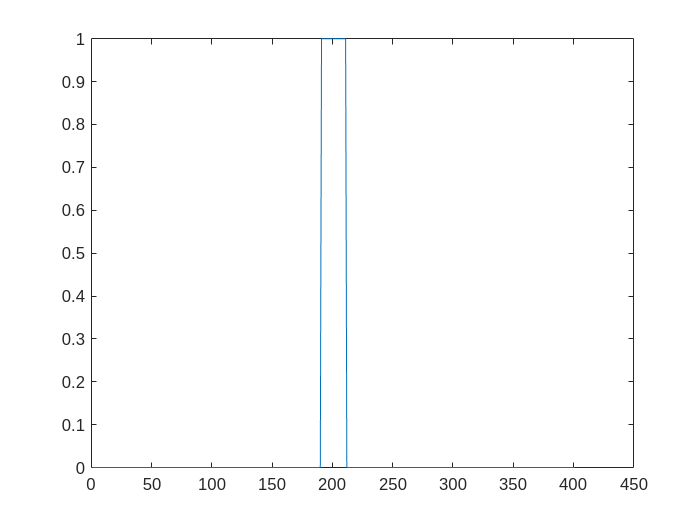

ventanacuad = zeros(1,lenf);
middle      = ceil(lenf/2); %200
coeff       = 20;
left        = (middle-coeff/2); %191
right       = (middle+coeff/2); %191
ventanacuad(left:right) = 1;
plot (ventanacuad)

Combinamos el filtro con nuestra ventana cuadrada. 

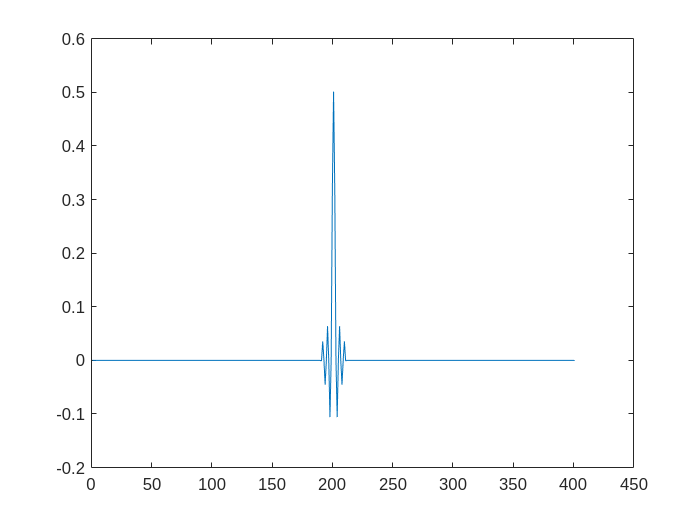

filtro_cuad=t_square.*ventanacuad;
plot(filtro_cuad);

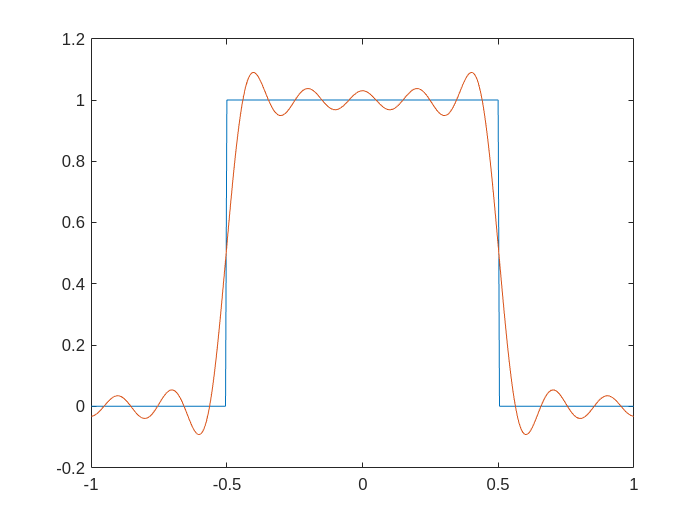

plot(frec,x);
hold on
plot(frec,real(ttof(filtro_cuad)))
hold off

### VON HAN 

Esta ventana es base para la de hamming. 

$w\left(n\right)=\ldotp 5\left(1-\cos \left(2\pi \frac{n}{N}\right)\right)$ donde $L=N+1$

Nota : No olvide normalizar la señal 

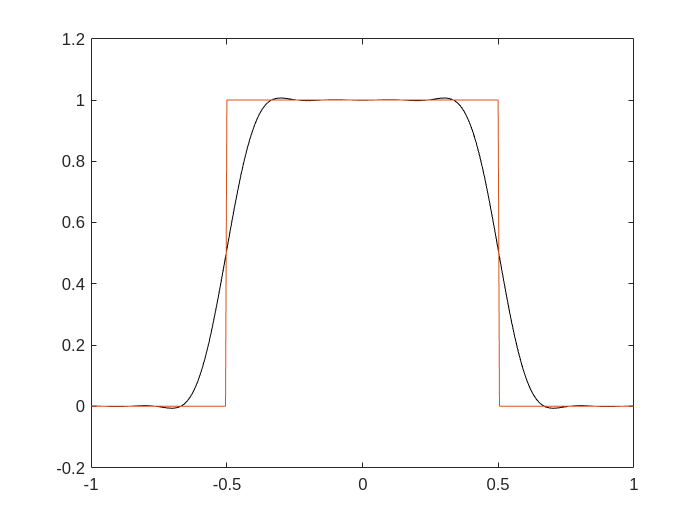


ventanavonhan=zeros(1,lenf);
coef = -10:1:10;
hann_window =.5.*(1-cos(2*pi.*coef./(length(coef)-1)));
hann_window = normalize((-1).*hann_window,'range');% ajustar la ventana de 0 a 1
ventanavonhan(191:211)=hann_window; % paso importante normalizar
filtro_hann = y.*ventanavonhan;
plot(frec,real(ttof(filtro_hann)), 'k');
hold on
plot(frec,x);
hold off

### **KAISER**

Desventaja: Alarga mas la caida

Ventaja; Tiene menos riso

Basada en las funciones de Bessel 

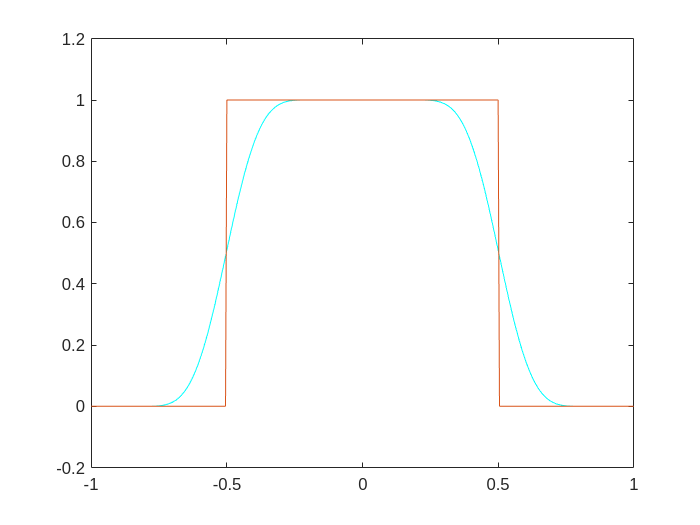

ventanakaiser=zeros(1,lenf);
ventanakaiser(191:211) = kaiser(21,8.85);
filtro3=t_square.*ventanakaiser;
plot(frec,real(ttof(filtro3)), 'c');
hold on
plot(frec,x);
hold off

### Ventana de hamming

**La ventana de Hamming es una de las utilizadas.**

Usaremos la ventan cuadrada y hacemos un ventana de hamming del mismo tamaño esto se usara para comparar despues. 

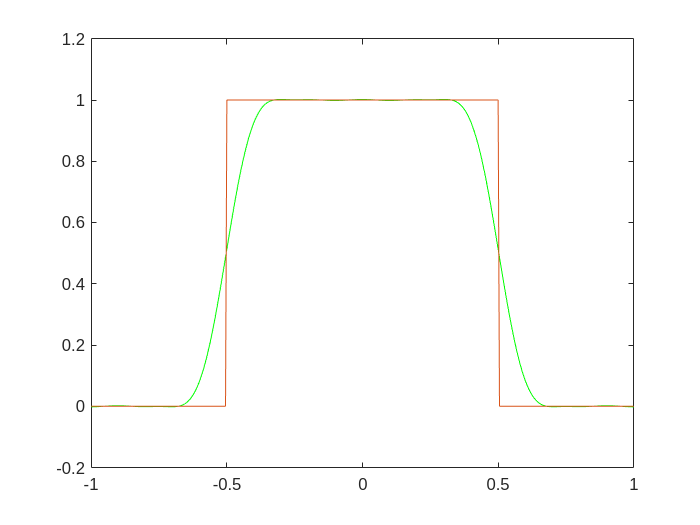

ventanahamm=zeros(1,lenf);
ventanahamm(191:211)=hamming(21); %Ventana Hamming con valor hasta 21
filtro=y.*ventanahamm;
plot(frec,real(ttof(filtro)), 'g');
hold on
plot(frec,x);
hold off

### **Hamming from the scratch**


$$W\left(n\right)=\ldotp 54-\ldotp 46\left(1-\cos \left(\frac{2\pi n}{N}\right)\right)$$


NOTE: no olvides normalizar la W(n)


ventanahamming=zeros(1,lenf);
coef = -10:1:10;
filter_cos =.54-.46*(1-cos(2*pi.*coef/(length(coef)-1)));
ventanahamming(191:211)=normalize (filter_cos,'range'); % paso importante 
filtro_hann = y.*ventanahamming;
plot(frec,real(ttof(filtro_hann)), 'k');
hold on
plot(frec,x);
hold off